# DCO Noise Model

## Modeling Oscillator Jitter

OSC的输出经过一系列buffer，从而对时钟边沿施加了随机扰动。每个周期边沿的抖动与前一周期无关，即符合独立不相关分布（independent and identically distributed, IID）。这种特性可以用附加白高斯噪声进行建模（additive white Gaussian noise, AWGN）。

第$i$周期的上升沿时刻$t_j [i] = iT_0 + \Delta t[i]$

第$i$周期中随机扰动带来的时间偏移量$TDEV_j [i] = \Delta t[i]$

jitter噪底为$\mathcal{L}$，注意这是SSB功率谱密度，和时域噪声能量的关系是：


$$\sigma_{\Delta t} = \frac{T_0}{2\pi}\sqrt{\mathcal{L}f_0}$$


## Modeling Oscillator Wander

时间游走，这一效应也称为accumulative jitter。OSC的震荡周期由于噪声而产生变化，与jitter不同，对于一个时钟边沿受到之前所有周期波动的影响。

第$i$周期的上升沿时刻$t_w [i] = iT_0 + \sum_{l=1}^{i}\Delta T[l]$

第$i$周期中周期扰动带来的时间偏移量$TDEV_w [i] = \sum_{l=1}^{i}\Delta T[l]$

由于存在积分效应，这部分噪声对应于OSC噪声模型种的-20dB/dec斜率的部分。积分过程引入了一个噪声传递函数$\frac{TDEV}{\Delta T}(z)=\frac{1}{1-z^{-1}}$

从z-domain到s-domain进行变换，$z=e^{j\omega/f_s}$ ，对$\Delta T$的噪声功率谱密度使用上面的传递函数进行转换，得到在频偏$\Delta f$处测量SSB噪声功率谱密度为$\mathcal{L}\{\Delta f\}$。


$$\mathcal{L}\{\Delta f\} = \left|\frac{f_0}{\Delta\omega}\right|^2 \left( \frac{2\pi}{T_0} \sigma_{\Delta T} \right)^2 \frac{1}{f_0} = \frac{f_0^3}{\Delta f^2}\sigma_{\Delta T}^2$$


从相噪SSB功率谱密度反推$\Delta T$的平均噪声功率


$$\sigma_{\Delta T} = \frac{\Delta f}{f_0}\sqrt{\mathcal{L}\{ \Delta f \} T_0 }$$


## Modeling Oscillator Flicker (1/f) Noise

将白噪声通过一系列低通滤波器来模拟1/f噪声，每一个滤波器整形出不同部分的噪声谱拟合出一个1/f噪声的斜率，slope=Adb/r=10dB/dec

前后两级滤波器的低通增益相差A倍，$A = 10^{A_{dB}/20}$，极点频率相隔r倍，$r = \frac{f_{c, k+1}}{f_{c, k}}$

采用一阶IIR滤波器，$y_k[i] = (1-a_k)y_k[i-1] + a_kA^{-(k-1)}x[i]$

近似的s-domain传递函数，$H_k(s) = \frac{a_k A^{-(k-1)} (1+s/f_s)}{s/f_s+a_k}$

根据极点频率给出滤波器参数$a_k =  2\pi \frac{f_{c,k}}{f_s}$

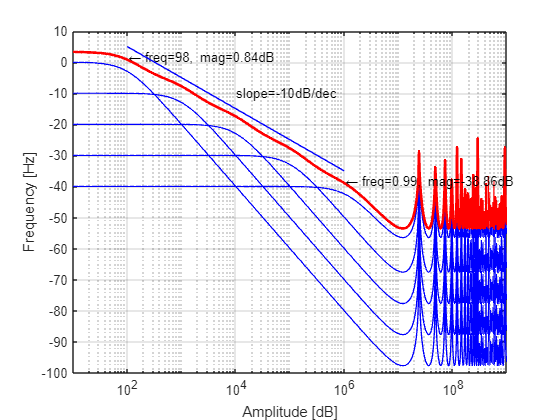

% iir filter corner frequency
f_c1 = 100;
f_c2 = 1e3;
f_c3 = 10e3;
f_c4 = 100e3;
f_c5 = 1e6;
% filter sampling frequency
Nos = 100;
f0 = 2.4e9;
fs_iir = f0/Nos;

% iir filter coefficients
A = 10^(10/20);
a1 = 2*pi * f_c1/fs_iir;
a2 = 2*pi * f_c2/fs_iir;
a3 = 2*pi * f_c3/fs_iir;
a4 = 2*pi * f_c4/fs_iir;
a5 = 2*pi * f_c5/fs_iir;

freq = logspace(1, 9, 800);
s = 1i*2*pi*freq;

% s-domain iir filter tf
z = exp(s/fs_iir);
h1 = a1*A^(0) ./ (1 - (1-a1)*z.^(-1));
h2 = a2*A^(-1) ./ (1 - (1-a2)*z.^(-1));
h3 = a3*A^(-2) ./ (1 - (1-a3)*z.^(-1));
h4 = a4*A^(-3) ./ (1 - (1-a4)*z.^(-1));
h5 = a5*A^(-4) ./ (1 - (1-a5)*z.^(-1));

h_tot = h1 + h2 + h3 + h4 + h5;

% 1/f noise response without sinc filtering
figure;
semilogx(freq, 20*log10(abs(h1)), ...
    freq, 20*log10(abs(h2)), ...
    freq, 20*log10(abs(h3)), ...
    freq, 20*log10(abs(h4)), ...
    freq, 20*log10(abs(h5)), 'LineWidth', 1, 'Color', [0 0 1]);
hold on;
semilogx(freq, 20*log10(abs(h_tot)), 'LineWidth', 2, 'Color', [1 0 0]);
grid on;

text(freq(100), 20*log10(abs(h_tot(100))), ...
    [ '\leftarrow', ...
    'freq=', num2str(round(freq(100)), '%d'), ...
    ', mag=', num2str(20*log10(abs(h_tot(100))), '%.2f'), ...
    'dB']);
text(freq(500), 20*log10(abs(h_tot(500))), ...
    [ '\leftarrow', ...
    'freq=', num2str(freq(500)/1e6, '%.2f'), ...
    ', mag=', num2str(20*log10(abs(h_tot(500))), '%.2f'), ...
    'dB']);

line([1e2 1e6], 5+[0 -40], 'Color', 'b');
text(1e4, -10, 'slope=-10dB/dec');

ax = gca;
ax.XLim = [1e1 1e9];
ax.YLim = [-100 10];
ax.XLabel.String = 'Amplitude [dB]';
ax.YLabel.String = 'Frequency [Hz]';

在bogdan书中，描述在1/f的corner frequency处由于一阶滤波的效果会导致3dB的衰减，需要在计算噪声功率时补偿回来，但是实际上从上图可以看出这部分的衰减已经被各级滤波器的幅度补偿了，100Hz处的幅度为0.76dB。但是最后在仿真中发现还是需要额外补偿3dB才能更让仿真和计算结果更接近。

因此，可以直接使用和wander noise相同的公式将平均噪声功率和相噪功率谱密度联系起来。


$$\sigma_{\Delta T, 1/f} = \frac{\Delta f_{c,1}}{f_0}\sqrt{2\mathcal{L}\{ \Delta f_{c,1} \} T_0 }$$


这个公式中使用的是最小的IIR滤波器拐点频率，这决定了对1/f噪声建模的最小频率。

此外，由于所有的IIR滤波器使用了相同的输入，他们的输出也带有相关性，因此需要对噪声功率进一步进行补偿。对于r=10的情况，$\mathcal{L}\{\Delta f_{c,1}\}$需要在原来的基础上减去5.5dB。

### sinc filtering

由于IIR滤波器采样率相对OSC震荡频率很低，在升采样之后IIR滤波器的输出会发生混叠，因此需要进行抗混叠滤波。并且IIR滤波器的输出在fs_iir频率上出现峰值（因为IIR滤波器的输出在频谱上按照fs_iir的频率进行搬移），为了抑制这个峰值，可以使用sinc filtering进行滤波。

实际上这个sinc filtering是在升采样的过程中自带的，首先信号按照fs_iir的频率进行采样从IIR滤波器中输出$x_{iir}[k]$。然后将信号$x_{iir}[k]$升采样到f0频率，再与一个N点矩形窗$h_{rec}[n]$进行卷积。这个采样过程中就已经引入了sinc滤波的效果。然后再用一阶IIR滤波器进行抗混叠滤波。

对于一个采样率为f0，采样N点的sinc filtering，其DTFT为


$$H_{rec}(j\omega) = \sum_{n=0}^{N-1}e^{-j\omega n}=\frac{1-e^{-j\omega N}}{1-e^{-j\omega}}$$


在引入sinc滤波和抗混叠滤波之后，需要保证信号的功率谱密度不被改变


$$\left| H_{rec}(j\omega) \right| = \left| \frac{sin(\frac{\omega N}{2})}{sin(\frac{\omega}{2})} \right|$$


这个式子中，N表示从fs_iir到f0的升采样率，低频增益为N。

抗混叠滤波前功率谱密度=白噪声功率/fs_iir*|Hiir|^2

抗混叠滤波后功率谱密度=白噪声功率/f0*|Hiir|^2*|Hrec|^2=抗混叠滤波前功率谱密度*N

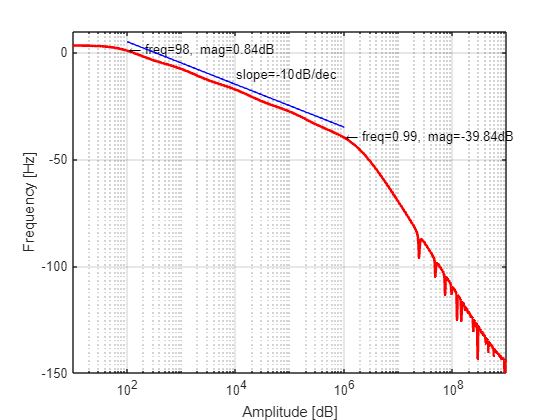

% iir filter corner frequency
f_caa = 2e6;

% iir filter coefficients
aa = 2*pi * f_caa/f0;

% s-domain anti-aliasing filter tf
z = exp(s/f0);
haa = aa ./ (1 - (1-aa)*z.^(-1));
hrec = (1-exp(-s/f0*Nos)) ./ (1-exp(-s/f0));

h_tot_aa = h_tot .* haa .* hrec /Nos;

% 1/f noise response with anti-aliasing filtering
figure;
semilogx(freq, 20*log10(abs(h_tot_aa)), 'LineWidth', 2, 'Color', [1 0 0]);
grid on;

text(freq(100), 20*log10(abs(h_tot_aa(100))), ...
    [ '\leftarrow', ...
    'freq=', num2str(round(freq(100)), '%d'), ...
    ', mag=', num2str(20*log10(abs(h_tot_aa(100))), '%.2f'), ...
    'dB']);
text(freq(500), 20*log10(abs(h_tot_aa(500))), ...
    [ '\leftarrow', ...
    'freq=', num2str(freq(500)/1e6, '%.2f'), ...
    ', mag=', num2str(20*log10(abs(h_tot_aa(500))), '%.2f'), ...
    'dB']);

line([1e2 1e6], 5+[0 -40], 'Color', 'b');
text(1e4, -10, 'slope=-10dB/dec');

ax = gca;
ax.XLim = [1e1 1e9];
ax.YLim = [-150 10];
ax.XLabel.String = 'Amplitude [dB]';
ax.YLabel.String = 'Frequency [Hz]';